#   NR Cell Performance Evaluation with Physical Layer Integration

This example demonstrates the integration of high fidelity 5G Toolbox™ physical layer in a 5G New Radio (NR) node. The example models a 5G NR cell consisting of a set of user equipment (UE) connected to a gNB. The NR stack on the nodes includes radio link control (RLC), medium access control (MAC), and physical (PHY) layers. The example also models channel impairments that you can customize. For faster MAC focused simulations you can switch to passthrough PHY layer or you can integrate with a custom PHY layer.

此示例演示了高保真 5G Toolbox™ 物理层在 5G 新无线电 (NR) 节点中的集成。该示例对由一组连接到 gNB 的用户设备 (UE) 组成的 5G NR 小区进行建模。节点上的 NR 堆栈包括无线电链路控制 (RLC)、媒体访问控制 (MAC) 和物理 (PHY) 层。该示例还对您可以自定义的通道损耗进行建模。您可以切换到直连的 PHY 层，也可以与自定义 PHY 层集成。

## Introduction

The example considers the following operations within gNB and UEs that facilitate uplink (UL) and downlink (DL) transmissions and receptions.该示例考虑了 gNB 和 UE 中促进上行链路 (UL) 和下行链路 (DL) 传输和接收的以下操作。

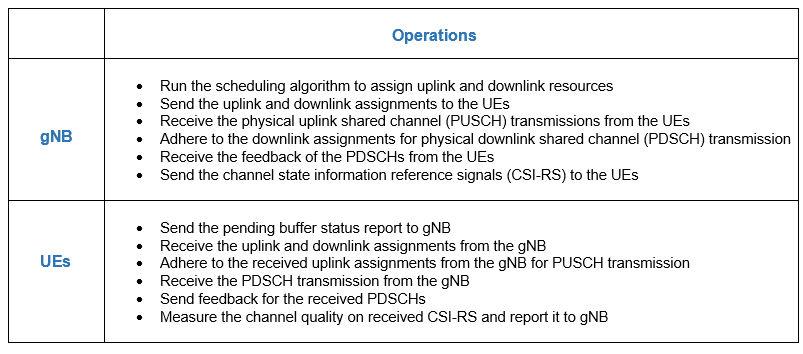

gNB：1）执行调度算法分配上下行资源；2）发送上行链路和下行链路分配信息给终端；3）接收来自UEs的物理上行共享通道(PUSCH)传输;4）支持物理下行共享信道(PDSCH)传输的下行链路分配；5）接收终端反馈的pdsch信息；6）向终端发送CSI-RS信号。

UEs：1）向gNB发送缓冲区状态报告；2）接收来自基站的上行和下行链路分配；3）根据从基站收到的上行链路分配进行PUSCH传输；4）接收来自gNB的PDSCH传输；5）对收到的pdsch发送反馈；6）测量接收到的CSI-RS上的信道质量并报告给基站。

The complete PUSCH or PDSCH packet is transmitted in the first symbol of its allocated symbol set. Receiver processes the packet in the symbol just after the last symbol in the allocated symbol set.

This example models:

- Slot based and symbol based DL and UL scheduling.

- Configurable subcarrier spacing resulting in different slot durations.

- Noncontiguous allocation of frequency-domain resources in terms of resource block groups (RBGs).

- Asynchronous adaptive hybrid automatic repeat request (HARQ) mechanism in UL and DL.

- PUSCH demodulation reference signal (DM-RS) and PDSCH DM-RS.

- DL channel quality measurement by UEs based on the CSI-RS received from gNB. By default, the CSI-RS resource element is transmitted in each slot for each resource block (RB) in DL bandwidth for all UEs. The same CSI-RS configuration is applicable to all the UEs. The example does not model the sounding reference signal (SRS) for measuring UL channel quality. UL channel quality is assumed to be the same as the DL channel quality measured on CSI-RS.

- Free space path loss (FSPL), additive white Gaussian noise (AWGN), and clustered delay line (CDL) propagation channel model.

- Single input single output (SISO) antenna configuration.

- Single bandwidth part across the whole carrier.

Control packets such as UL assignment, DL assignment, buffer status report (BSR), PDSCH feedback, and channel quality indicator (CQI) report, are assumed to be sent out of band, that is, without the need of resources for transmission and assured error-free reception.

完整的 PUSCH 或 PDSCH 分组在其分配的符号集的第一个符号中传输。接收器处理分配符号集中最后一个符号之后的符号中的数据包。

此示例模型：

- 基于时隙和基于符号的 DL 和 UL 调度。

- 可配置的子载波间隔导致不同的时隙持续时间。

- 根据资源块组 (RBG) 对频域资源进行非连续分配。

- UL和DL中的异步自适应混合自动重复请求（HARQ）机制。

- PUSCH 解调参考信号 (DM-RS) 和 PDSCH DM-RS。

- UE 基于从 gNB 接收到的 CSI-RS 进行 DL 信道质量测量。默认情况下，CSI-RS 资源元素在所有 UE 的 DL 带宽中的每个资源块 (RB) 的每个时隙中传输。相同的 CSI-RS 配置适用于所有 UE。该示例未对用于测量 UL 信道质量的探测参考信号 (SRS) 建模。假设 UL 信道质量与在 CSI-RS 上测量的 DL 信道质量相同。

- 自由空间路径损耗 (FSPL)、加性高斯白噪声 (AWGN) 和聚集延迟线 (CDL) 传播信道模型。

- 单输入单输出 (SISO) 天线配置。

- 整个载波的单一带宽部分。

控制数据包，如 UL 分配、DL 分配、缓冲区状态报告 (BSR)、PDSCH 反馈和信道质量指示 (CQI) 报告，被假定为带外发送，即无需资源进行传输并保证无差错接收。

## **NR Protocol Stack  NR协议栈**

A node (gNB or UE) is a composition of NR stack layers. The helper classes [hNRGNB.m](matlab:edit('hNRGNB')) and [hNRUE.m](matlab:edit('hNRUE')) create gNB and UE nodes respectively, containing the RLC, MAC, and PHY layers.

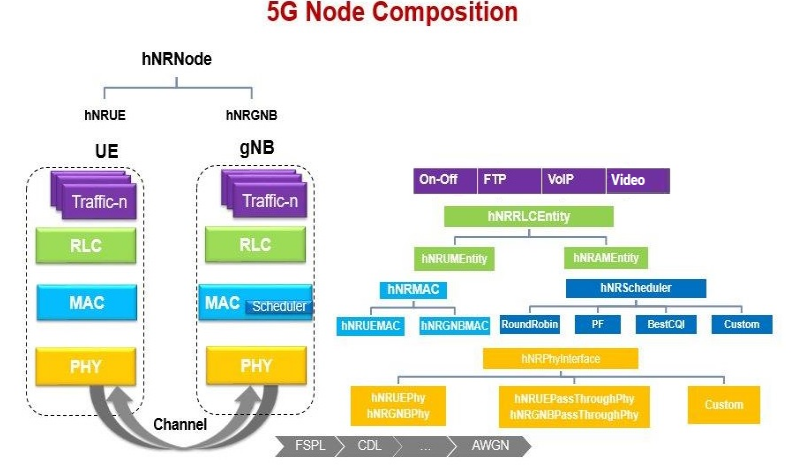

### RLC Layer

RLC operates in unacknowledged mode (UM) with a single logical channel (LCH). For the RLC layer, both [hNRGNB.m](matlab:edit('hNRGNB')) and [hNRUE.m](matlab:edit('hNRUE')) use [hNRUMEntity.m](matlab:edit('hNRUMEntity')) to implement the functionality of both the RLC transmitter and receiver.

RLC 以单逻辑信道 (LCH) 的未确认模式 (UM) 运行。对于 RLC 层，[hNRGNB.m](matlab:edit('hNRGNB'))和[hNRUE.m](matlab:edit('hNRUE'))都使用[hNRUMEntity.m](matlab:edit('hNRUMEntity'))来实现 RLC 发送器和接收器的功能。

### **MAC Layer**

For the MAC layer, [hNRGNB.m](matlab:edit('hNRGNB')) uses the helper class [hNRGNBMAC.m](matlab:edit('hNRGNBMAC')) to implement the gNB MAC functionality and [hNRUE.m](matlab:edit('hNRUE')) uses [hNRUEMAC.m](matlab:edit('hNRUEMAC')) to implement the UE MAC functionality. gNB MAC has UL and DL schedulers that assign UL and DL resources, respectively to the UEs. For more details about UL and DL scheduling to assign the PUSCH and the PDSCH resources, see the [NR FDD Scheduling Performance Evaluation](docid:5g_ug#mw_12d91b71-808a-45f1-bd06-5776780aafff) example. Schedulers are implemented in [hNRSchedulerRoundRobin.m](matlab:edit('hNRSchedulerRoundRobin')) (Round-robin strategy), [hNRSchedulerProportionalFair.m](matlab:edit('hNRSchedulerProportionalFair')) (Proportional fair strategy), and [hNRSchedulerBestCQI.m](matlab:edit('hNRSchedulerBestCQI')) (Best CQI strategy) helper classes. All these schedulers are inherited from the base class [hNRScheduler.m](matlab:edit('hNRScheduler')), which contains the core scheduling functionality. 

对于 MAC 层，[hNRGNB.m](matlab:edit('hNRGNB'))使用类[hNRGNBMAC.m](matlab:edit('hNRGNBMAC'))来实现 gNB MAC 功能，而[hNRUE.m](matlab:edit('hNRUE'))使用[hNRUEMAC.m](matlab:edit('hNRUEMAC'))来实现 UE MAC 功能。gNB MAC 具有分别为 UE 分配 UL 和 DL 资源的 UL 和 DL 调度器。

有关分配 PUSCH 和 PDSCH 资源的 UL 和 DL 调度的更多详细信息，请参阅[NR FDD 调度性能评估](https://ww2.mathworks.cn/help/5g/ug/nr-fdd-scheduling-performance-evaluation.html)示例。（调度器（UL 和 DL）每*p*个时隙运行一次以分配 UL 和 DL 资源，其中*p*是调度器的配置周期。在每次运行中，调度的时隙数等于调度程序运行的周期*p*。所有调度程序都继承自包含核心调度功能的类[hNRScheduler.m](matlab:edit('hNRScheduler'))。）调度器在[hNRSchedulerRoundRobin.m](matlab:edit('hNRSchedulerRoundRobin'))（循环策略）、[hNRSchedulerProportionalFair.m](matlab:edit('hNRSchedulerProportionalFair'))（比例公平策略）和[hNRSchedulerBestCQI.m 中实现](matlab:edit('hNRSchedulerBestCQI'))（最佳 CQI 策略）助手类。

### PHY Layer and Channel Modeling

The example uses 5G Toolbox™ for PHY layer operations of UE and gNB. On the Tx side, the operations involve the physical layer processing of a transport block received from MAC and its transmission. On the Rx side, there is processing of received waveform and sending the decoded information to MAC. For more details on PDSCH and PUSCH processing chains, refer to the [NR PDSCH Throughput](docid:5g_ug#mw_new-radio-pdsch-throughput) example and [NR PUSCH Throughput](docid:5g_ug#mw_aec3475a-aecc-4d83-b504-0971620c97eb) example, respectively. For the PHY layer, [hNRGNB.m](matlab:edit('hNRGNB')) uses the helper class [hNRGNBPhy.m](matlab:edit('hNRGNBPhy')) to implement the gNB PHY layer functionality and [hNRUE.m](matlab:edit('hNRUE')) uses [hNRUEPhy.m](matlab:edit('hNRUEPhy')) to implement the UE PHY layer functionality. For channel impairments, the example models FSPL, AWGN, and the CDL propagation channel model.

The example uses a lookup table to map the received signal-to-interference-plus-noise ratio (SINR) to CQI index for 0.1 block error rate (BLER). The lookup table corresponds to the CQI table as per 3GPP TS 38.214 Table 5.2.2.1-3. For more information about the process of generating this lookup table, refer to [5G NR Downlink CSI Reporting](docid:5g_ug#mw_d1f89a94-4ef9-4f57-9301-212f082e187e) example.

该示例使用 5G Toolbox™ 进行 UE 和 gNB 的 PHY 层操作。在 Tx 端，操作包括从 MAC 接收的传输块的物理层处理及其传输。在 Rx 端，对接收到的波形进行处理，并将解码后的信息发送到 MAC。有关 PDSCH 和 PUSCH 处理链的更多详细信息，请分别参考[NR PDSCH 吞吐量](https://ww2.mathworks.cn/help/5g/ug/nr-pdsch-throughput.html)示例和[NR PUSCH 吞吐量](https://ww2.mathworks.cn/help/5g/ug/nr-pusch-throughput.html)示例。（NR PDSCH 吞吐量：该示例实现了 PDSCH 和下行链路共享信道 (DL-SCH)。发射机模型包括PDSCH解调参考信号（DM-RS）和PDSCH相位跟踪参考信号（PT-RS）。该示例支持集群延迟线 (CDL) 和抽头延迟线 (TDL) 传播通道。**您可以执行完美或实用的同步和信道估计。为了减少总仿真时间，您可以使用 Parallel Computing Toolbox™ 并行执行 SNR 循环中的 SNR 点。**同理上行也差不多）

对于 PHY 层，[hNRGNB.m](matlab:edit('hNRGNB'))使用帮助类[hNRGNBPhy.m](matlab:edit('hNRGNBPhy'))来实现 gNB PHY 层功能，[hNRUE.m](matlab:edit('hNRUE'))使用[hNRUEPhy.m](matlab:edit('hNRUEPhy'))实现 UE PHY 层功能。对于信道损耗，示例模型 FSPL、AWGN 和 CDL 传播信道模型（标准中一般用TDL模型）。

该示例使用**查找表**将接收到的信号干扰加噪声比 (SINR) 映射到 CQI 索引，以获得 0.1 误块率 (BLER)。查找表对应于根据 3GPP TS 38.214 表 5.2.2.1-3 的 CQI 表。有关生成此查找表的过程的更多信息，请参阅[5G NR 下行链路 CSI 报告](https://ww2.mathworks.cn/help/5g/ug/5g-nr-downlink-csi-reporting.html)示例。

### MAC-PHY Interface

Following are the major interface calls between the MAC layer and PHY layer. For more details, refer to [hNRPhyInterface.m](matlab:edit('hNRPhyInterface.m')).

- `txDataRequest:` The request from MAC to PHY to transmit either PDSCH (by gNB) or PUSCH (by UE). MAC calls this request at the start of Tx time. The PHY processing time is not modeled in this example.

- `rxDataRequest:` The request from MAC to PHY to receive either PUSCH (by gNB) or PDSCH (by UE). MAC calls this request at the start of Rx time.

- `dlControlRequest:` The request from MAC to PHY for non-data downlink transmissions or receptions. For gNB, this request is sent by gNB MAC for DL transmissions. For UE, it is sent by UE MAC for DL receptions. MAC sends the request at the start of a DL slot for all the scheduled DL transmission or receptions in the slot. This interface is used for all the DL transmission and receptions, except PDSCH. `txDataRequest` and `rxDataRequest` are used for PDSCH. In this example, gNB MAC uses this interface to send CSI-RS, and UE MAC uses it to receive CSI-RS.

- `registerMACInterfaceFcn:` The one-time setup call to register MAC callback functions at PHY. PHY uses the callbacks to send information up the stack to MAC. gNB PHY uses the callback to send decoded UL packets to MAC. UE PHY uses the callbacks to send decoded DL packets and DL channel quality measured on CSI-RS to MAC.

以下是 MAC 层和 PHY 层之间的主要接口调用。有关更多详细信息，请参阅[hNRPhyInterface.m](matlab:edit('hNRPhyInterface.m'))。

- `txDataRequest:`MAC 向 PHY 发送 PDSCH（通过 gNB）或 PUSCH（通过 UE）的请求。MAC 在 Tx 时间开始时调用此请求。**此示例中未对 PHY 处理时间进行建模。**

- `rxDataRequest:`MAC 到 PHY 接收 PUSCH（通过 gNB）或 PDSCH（通过 UE）的请求。MAC 在 Rx 时间开始时调用此请求。

- `dlControlRequest:`MAC 到 PHY 的非数据下行传输或接收请求。对于 gNB，此请求由 gNB MAC 发送以进行 DL 传输。对于 UE，它由 UE MAC 发送用于 DL 接收。MAC 在 DL 时隙开始时发送该时隙中所有已调度的 DL 传输或接收的请求。该接口用于除 PDSCH 之外的所有 DL 传输和接收。`txDataRequesth和rxDataRequest`用于 PDSCH。在本例中，gNB MAC 使用该接口发送 CSI-RS，UE MAC 使用该接口接收 CSI-RS。

- `registerMACInterfaceFcn:`在PHY上注册MAC回调函数的一次性设置调用。PHY 使用回调将信息沿协议栈向上发送到 MAC。gNB PHY 使用回调将解码的 UL 数据包发送到 MAC。UE PHY 使用回调将解码的 DL 数据包和在 CSI-RS 上测量的 DL 信道质量发送到 MAC。

### Pluggable PHY  封装的物理层

You can plug and use different variations of PHY layer in your system. In a simulation run, all the nodes use the same variation of the PHY layer. The MAC is unaware of the type of PHY layer underneath, because the MAC uses the MAC-PHY interface to interact with the PHY layer. By default the example uses 5G Toolbox™ to model the PHY layer. To use a passthrough PHY layer, refer to [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3), [NR FDD Scheduling Performance Evaluation](docid:5g_ug#mw_12d91b71-808a-45f1-bd06-5776780aafff), and [NR TDD Symbol Based Scheduling Performance Evaluation](docid:5g_ug#mw_2cf57929-defe-49f8-9be4-19cd760ceee1) examples. A passthrough PHY layer does not do any physical layer processing of packets.

您可以在系统中封装和使用不同的 PHY 层。在模拟运行中，所有节点都使用相同的 PHY 层。MAC 不知道下面的 PHY 层的类型，因为 MAC 使用 MAC-PHY 接口与 PHY 层交互。默认情况下，该示例使用 5G Toolbox™ 对 PHY 层进行建模。

如果要使用直连的 PHY 层，请参阅[NR PUSCH FDD 调度](https://ww2.mathworks.cn/help/5g/ug/nr-pusch-scheduling-fdd.html)、[NR FDD 调度性能评估](https://ww2.mathworks.cn/help/5g/ug/nr-fdd-scheduling-performance-evaluation.html)和[NR TDD 基于符号的调度性能评估](https://ww2.mathworks.cn/help/5g/ug/nr-tdd-symbol-based-scheduling-performance-evaluation.html)示例。直连 PHY 层不对数据包进行任何物理层处理。

## Scenario Configuration

Configure simulation parameters in the `simParameters` structure.

rng('default'); % Reset the random number generator产生伪随机数有一个种子，所谓的伪随机就是指有一定“规律”，而这个种子就是这个“规律”。rng(‘default’)就是用默认种子。每次产生相同的随机数
simParameters = []; % Clear the simParameters variable
simParameters.NumFramesSim = 10; % 仿真实验有多少帧Simulation time in terms of number of 10 ms frames-------------
simParameters.SchedulingType = 1; % Set the value to 0 (slot based scheduling) or 1 (symbol based scheduling)将值设置为 0（基于时隙的调度）或 1（基于符号的调度）---------

Specify the number of UEs in the cell, assuming that UEs have sequential radio network temporary identifiers (RNTIs) from `1` to `simParameters.NumUEs`. If you change the number of UEs, ensure that the number of rows in `simParameters.UEPosition` parameter equals to the value of `simParameters.NumUEs`.指定小区中 UE 的数量并验证UE位置

simParameters.NumUEs = 4;
% Assign position to the UEs assuming that the gNB is at (0, 0, 0). N-by-3
% matrix where 'N' is the number of UEs. Each row has (x, y, z) position of a
% UE (in meters)
simParameters.UEPosition = [15 0 0;
                            35 0 0;
                            65 0 0;
                            90 0 0];
% simParameters.UEPosition = [100 0 0;
%                             350 0 0;
%                             650 0 0;
%                             900 0 0];
simParameters.UESpeed = 5;% Supported speed: '5/10/15/20/25'
% Validate the UE positions
validateattributes(simParameters.UEPosition, {'numeric'}, {'nonempty', 'real', 'nrows', simParameters.NumUEs, 'ncols', 3, 'finite'}, 'simParameters.UEPosition', 'UEPosition')

Set the channel bandwidth to 5 MHz and subcarrier spacing (SCS) to 15 kHz as defined in 3GPP TS 38.104 Section 5.3.2. The complete bandwidth is assumed to be allotted for PUSCH or PDSCH.

simParameters.NumRBs = 66;%-------------------
simParameters.SCS = 60; % kHz-----------------------
simParameters.DLCarrierFreq = 2.635e9; % Hz
simParameters.ULCarrierFreq = 2.515e9; % Hz
% The UL and DL carriers are assumed to have symmetric channel假设 UL 和 DL 载波具有对称信道？
% bandwidth 将信道带宽设置为 5 MHz，
simParameters.DLBandwidth = 50e6; % 50MHz --------------------
simParameters.ULBandwidth = 50e6; % Hz------------------------

Specify the transmit power and antenna gain.

simParameters.UETxPower = 23; % Tx power for all the UEs in dBm  
simParameters.GNBTxPower = 24; % Tx power for gNB in dBm   24  --------------------------
simParameters.GNBRxGain = 5; % Receiver antenna gain at gNB   5-------------------------

**Specify the SINR to a CQI index mapping table for a BLER of 0.1.**

load('SINR90pc.mat');
simParameters.SINR90pc = SINR90pc;

Specify the scheduling strategy and the maximum limit on the RBs allotted for PDSCH and PUSCH. The transmission limit applies only to new transmissions and not to the retransmissions.

simParameters.SchedulerStrategy = 'a-PF'; % Supported scheduling strategies: 'a-PF','PF', 'RR', and 'BestCQI'
simParameters.RBAllocationLimitUL = 66; % For PUSCH -----------------------
simParameters.RBAllocationLimitDL = 66; % For PDSCH---------------------------

### Logical Channel Configuration-FDD引进

Load the logical channel configuration table. Each row in the table represents one logical channel and has these properties as columns.

- RNTI - Radio network temporary identifier of the UE.

- LogicalChannelID - Logical channel identifier.

- LCGID - Logical channel group identifier.

- SeqNumFieldLength - Defines the sequence number field length. It takes either 6 or 12.

- MaxTxBufferSDUs - Maximum Tx buffer size in terms of number of higher layer service data units (SDUs).

- ReassemblyTimer - Defines the reassembly timer (in ms).

- EntityType - Defines the RLC entity type. It takes values 0, 1, and 2, which indicates whether the RLC UM entity is unidirectional DL, unidirectional UL, or bidirectional UM, respectively.

- Priority - Priority of the logical channel.

- PBR - Prioritized bit rate (in kilo bytes per second).

- BSD - Bucket size duration (in ms).

加载逻辑通道配置表。表中的每一行代表一个逻辑通道，并将这些属性作为列。

- RNTI - UE 的无线网络临时标识符。

- LogicalChannelID - 逻辑通道标识符。

- LCGID - 逻辑通道组标识符。

- SeqNumFieldLength - 定义序列号字段长度。它需要 6 或 12。

- MaxTxBufferSDUs - 以更高层服务数据单元 (SDU) 的数量表示的最大 Tx 缓冲区大小。

- ReassemblyTimer - 定义重组计时器（以毫秒为单位）。

- EntityType - 定义 RLC 实体类型。它取值 0、1 和 2，分别指示 RLC UM 实体是单向 DL、单向 UL 还是双向 UM。

- 优先级 - 逻辑信道的优先级。

- PBR - 优先比特率（以千字节每秒为单位）。

- BSD - 存储桶大小持续时间（以毫秒为单位）。

% added by cyl
RLCChannelConfig=readtable("NRFDDRLCChannelConfig_xlsx.xlsx");
save("NRFDDRLCChannelConfig.mat","RLCChannelConfig");

load('NRFDDRLCChannelConfig.mat')
simParameters.RLCChannelConfig = RLCChannelConfig;

### Logging and visualization configuration

The `CQIVisualization` and `RBVisualization` parameters control the display of the CQI visualization and the RB assignment visualization respectively. To enable these visualization plots, set these parameters to `true`.

simParameters.CQIVisualization = false;
simParameters.RBVisualization = false;
simParameters.TimeVisualization = false;

Set the `enableTraces` as `true` to log the traces. If the `enableTraces` is set to `false`, then `CQIVisualization` and `RBVisualization` are disabled automatically and traces are not logged in the simulation. To speed up the simulation, set the `enableTraces` to `false`.要加快模拟速度，请将 设置`enableTraces`为`false`。

enableTraces = true;

The example updates the metrics plots periodically. Set the number of updates during the simulation.指标更新次数

simParameters.NumMetricsSteps = 10;   %20

Write the logs to MAT-files. The example uses these logs for post-simulation analysis and visualization.

parametersLogFile = 'simParameters'; % For logging the simulation parameters
simulationLogFile = 'simulationLogs'; % For logging the simulation traces
simulationMetricsFile = 'simulationMetrics'; % For logging the simulation metrics

% Enable packet capture (PCAP)   启用数据包捕获 (PCAP) 
simParameters.PCAPLogging = false; % Set the value to true to enable packet capture for UE of Interest
simParameters.UEofInterest = 1; % Log the packets of UE with this RNTI

### 原版Application traffic configuration

Set the DL and UL application traffic pattern for UEs.  设置应用数据速率

% dlAppDataRate = 16e4*ones(simParameters.NumUEs,1); % DL application data rate in kilo bits per second (kbps)
% ulAppDataRate = 16e4*ones(simParameters.NumUEs,1); % UL application data rate in kbps
% % Validate the DL application data rate
% validateattributes(dlAppDataRate, {'numeric'}, {'nonempty', 'vector', 'numel', simParameters.NumUEs, 'finite', '>', 0}, 'dlAppDataRate', 'dlAppDataRate')
% % Validate the UL application data rate
% validateattributes(ulAppDataRate, {'numeric'}, {'nonempty', 'vector', 'numel', simParameters.NumUEs, 'finite', '>', 0}, 'ulAppDataRate', 'ulAppDataRate')


### FDD-Application Traffic Configuration

Load the application configuration table containing these fields. Each row in the table represents one application and has these properties as columns.

- DataRate - Application traffic generation rate (in kilo bits per second).

- PacketSize - Size of the packet (in bytes).

- HostDevice - Defines the device (UE or gNB) on which the application is installed with the specified configuration. The device takes values 0 or 1. The values indicate the application is configured on gNB side or UE side, respectively.

- RNTI - Radio network temporary identifier of a UE. This identifies the UE for which the application is installed.

- LCID - Logical channel identifier.

% added by cyl
AppConfig=readtable("NRFDDAppConfig_xlsx.xlsx");
save("NRFDDAppConfig.mat","AppConfig");

load('NRFDDAppConfig.mat');
% Validate the host device type for the applications configured
validateattributes(AppConfig.HostDevice, {'numeric'}, {'nonempty', 'integer', '>=', 0, '<=', 1}, 'AppConfig.HostDevice', 'HostDevice');

## Derived Parameters

Compute the derived parameters based on the primary configuration parameters specified in the previous section and set some example-specific constants.

simParameters.DuplexMode = 0; % FDD
simParameters.NCellID = 1; % Physical cell ID
simParameters.Position = [0 0 0]; % Position of gNB in (x,y,z) coordinates

Specify the CSI-RS resource configuration, assuming that all UEs measure channel quality on the same CSI-RS resource.

csirsConfig = nrCSIRSConfig('NID', simParameters.NCellID, 'NumRB', simParameters.NumRBs, 'RowNumber', 2, 'SubcarrierLocations', 1, 'SymbolLocations', 0);
simParameters.CSIRSConfig = {csirsConfig};

Specify the CSI report configuration.指定 CSI 报告配置。

csiReportConfig = struct('SubbandSize', 8 , 'CQIMode', 'Subband');
simParameters.CSIReportConfig = {csiReportConfig};

Configure the channel model.配置通道模型。

channelModelUL = cell(1, simParameters.NumUEs);
channelModelDL = cell(1, simParameters.NumUEs);
waveformInfo = nrOFDMInfo(simParameters.NumRBs, simParameters.SCS);
for ueIdx = 1:simParameters.NumUEs
    % Configure the uplink channel model
    channel = nrCDLChannel;
    channel.DelayProfile = 'CDL-C';
    channel.DelaySpread = 100e-9;
    channel.Seed = 73 + (ueIdx - 1);%73 默认mt19937ar 随机数流的初始种子，指定为非负数值标量。
    channel.CarrierFrequency = simParameters.ULCarrierFreq;
    channel.TransmitAntennaArray.Size = [1 1 1 1 1];
    channel.ReceiveAntennaArray.Size = [1 1 1 1 1];
    channel.SampleRate = waveformInfo.SampleRate;
    channelModelUL{ueIdx} = channel;

    % Configure the downlink channel model
    channel = nrCDLChannel;%------------------------
    channel.DelayProfile = 'CDL-C';
    channel.DelaySpread = 100e-9;
    channel.Seed = 73 + (ueIdx - 1);
    channel.CarrierFrequency = simParameters.DLCarrierFreq;
    channel.TransmitAntennaArray.Size = [1 1 1 1 1];
    channel.ReceiveAntennaArray.Size = [1 1 1 1 1];
    channel.SampleRate = waveformInfo.SampleRate;
    channelModelDL{ueIdx} = channel;

%     channel = nrTDLChannel;
%     channel.Seed = 73 + (ueIdx - 1);
%     channel.DelayProfile = 'TDL-C';
%     channel.DelaySpread = 30e-9;
%     channel.MaximumDopplerShift = 50;
%     channel.NumTransmitAntennas = 1;
%     channel.NumReceiveAntennas = 1;
%     channel.SampleRate = waveformInfo.SampleRate;
%     channelModelUL{ueIdx} = channel;
% 
%     channel = nrTDLChannel;
%     channel.Seed = 73 + (ueIdx - 1);
%     channel.DelayProfile = 'TDL-C';
%     channel.DelaySpread = 30e-9;
%     channel.MaximumDopplerShift = 50;
%     channel.NumTransmitAntennas = 1;
%     channel.NumReceiveAntennas = 1;
%     channel.SampleRate = waveformInfo.SampleRate;
%     channelModelDL{ueIdx} = channel;

end

Set the PUSCH preparation time for UEs. The gNB ensures that PUSCH assignment is received at UEs `PUSCHPrepTime` ahead of the transmission time.设置 UE 的 PUSCH 准备时间。gNB 确保`PUSCHPrepTime`在传输时间之前在 UE 处接收到 PUSCH 分配。

simParameters.PUSCHPrepTime = 200; % In microseconds

Compute the slot duration for the selected SCS and the number of slots in a 10 ms frame.计算所选 SCS 的时隙持续时间和 10 ms 帧中的时隙数。

slotDuration = 1/(simParameters.SCS/15); % In ms 一个slot多少毫秒 0.5ms-30khz
numSlotsFrame = 10/slotDuration; % Number of slots in a 10 ms frame
numSlotsSim = simParameters.NumFramesSim * numSlotsFrame; % Number of slots in the simulation

Set the interval at which the example updates metrics visualization in terms of number of slots. Because this example uses a time granularity of one slot, the `MetricsStepSize` field must be an integer.由于此示例使用一个时隙的时间粒度，因此该`MetricsStepSize`字段必须是整数。

simParameters.MetricsStepSize = ceil(numSlotsSim / simParameters.NumMetricsSteps);
if mod(numSlotsSim, simParameters.NumMetricsSteps) ~= 0
    % Update the NumMetricsSteps parameter if numSlotsSim is not
    % completely divisible by it
    simParameters.NumMetricsSteps = floor(numSlotsSim / simParameters.MetricsStepSize);
end

原版：Specify one logical channel for each UE, and set the logical channel configuration for all nodes (UEs and gNBs) in the example.

%numLogicalChannels = 1; % Only 1 logical channel is assumed in each UE in this example
% Logical channel id (logical channel ID of data radio bearers starts from 4) 
%simParameters.LCHConfig.LCID = 4;

修改后的：Get the logical channel information associated per UE. This information helps in RLC metrics logging and visualization.

lchInfo = repmat(struct('RNTI', [], 'LCID', [], 'EntityDir', []), [simParameters.NumUEs 1]);
for ueIdx = 1:simParameters.NumUEs
    lchInfo(ueIdx).RNTI = ueIdx;
    lchInfo(ueIdx).LCID = simParameters.RLCChannelConfig.LogicalChannelID(simParameters.RLCChannelConfig.RNTI == ueIdx);
    lchInfo(ueIdx).EntityDir = simParameters.RLCChannelConfig.EntityType(simParameters.RLCChannelConfig.RNTI == ueIdx);
end

----------------原版的RLC配置，引用FDD那种就不需要了-------------------------

Specify the RLC entity type in the range [0, 3]. The values 0, 1, 2, and 3 indicate RLC UM unidirectional DL entity, RLC UM unidirectional UL entity, RLC UM bidirectional entity, and RLC AM entity, respectively.

% simParameters.RLCConfig.EntityType = 2;%RLC UM 双向实体RLC不做重传ARQ处理。

Create RLC channel configuration structure.

% rlcChannelConfigStruct.LCGID = 1; % Mapping between logical channel and logical channel group ID
% rlcChannelConfigStruct.Priority = 1; % Priority of each logical channel
% rlcChannelConfigStruct.PBR = 8; % Prioritized bitrate (PBR), in kilobytes per second, of each logical channel
% rlcChannelConfigStruct.BSD = 10; % Bucket size duration (BSD), in ms, of each logical channel
% rlcChannelConfigStruct.EntityType = simParameters.RLCConfig.EntityType;
% rlcChannelConfigStruct.LogicalChannelID = simParameters.LCHConfig.LCID;

--------------------------------以上不需要-------------

Set the simulation tick granularity (in terms of OFDM symbols) and the mapping type as per the configured scheduling type.根据配置的调度类型设置模拟滴答粒度（以 OFDM 符号为单位）和映射类型。

if ~isfield(simParameters, 'SchedulingType') || simParameters.SchedulingType == 0 % If no scheduling type is specified or slot based scheduling is specified
    tickGranularity = 14;
    simParameters.PUSCHMappingType = 'A';
    simParameters.PDSCHMappingType = 'A';
else % Symbol based scheduling
    tickGranularity = 1;
    simParameters.PUSCHMappingType = 'B';
    simParameters.PDSCHMappingType = 'B';
end

## gNB and UEs Setup

Create the gNB and UE objects, initialize the channel quality information for UEs, and set up the logical channel at gNB and UE. The helper classes [hNRGNB.m](matlab:edit('hNRGNB')) and [hNRUE.m](matlab:edit('hNRUE')) create gNB node and UE node respectively, containing the RLC, MAC and PHY layers.

**改了调度算法alpha-**

gNB = hNRGNB(simParameters); % Create gNB node

错误使用 hNRGNB
不能在类 'hNRNode' 中定义属性 'DistanceCalculatorFcn'，因为已在超类 'comm_sysmod.internal.wirelessNode' 中定义该属性。

% Create scheduler
switch(simParameters.SchedulerStrategy)
    case 'RR' % Round-robin scheduler
        scheduler = hNRSchedulerRoundRobin(simParameters);
    case 'PF' % Proportional fair scheduler
        scheduler = hNRSchedulerProportionalFair(simParameters);
    case 'a-PF' % alpha-Proportional fair scheduler
        scheduler = hNRScheduleralphaProportionalFair(simParameters);
    case 'BestCQI' % Best CQI scheduler
        scheduler = hNRSchedulerBestCQI(simParameters);
end
addScheduler(gNB, scheduler); % Add scheduler to gNB；gnb中的function
simParameters.ChannelModel = channelModelUL;                       
gNB.PhyEntity = hNRGNBPhy(simParameters); % Create the PHY layer instance
configurePhy(gNB, simParameters); % Configure the PHY layer
setPhyInterface(gNB); % Set the interface to PHY layer

% Create the set of UE nodes
UEs = cell(simParameters.NumUEs, 1);
for ueIdx=1:simParameters.NumUEs
    ueParam = simParameters;
    ueParam.Position = simParameters.UEPosition(ueIdx, :); % Position of the UE----------------
    ueParam.ChannelModel = channelModelDL{ueIdx};
    ueParam.CSIReportConfig = csiReportConfig;
    UEs{ueIdx} = hNRUE(ueParam, ueIdx);
    UEs{ueIdx}.PhyEntity = hNRUEPhy(ueParam, ueIdx); % Create the PHY layer instance
    configurePhy(UEs{ueIdx}, ueParam); % Configure the PHY layer
    setPhyInterface(UEs{ueIdx}); % Set up the interface to PHY layer

    % Setup logical channel at gNB for the UE   在 gNB 为 UE 建立逻辑信道----------
    %configureLogicalChannel(gNB, ueIdx, rlcChannelConfigStruct);
    % Setup logical channel at UE  % 在 UE 建立逻辑信道---------
    %configureLogicalChannel(UEs{ueIdx}, ueIdx, rlcChannelConfigStruct);
    %------------------------
end


% Setup logical channels
for lchInfoIdx = 1:size(simParameters.RLCChannelConfig, 1)
    rlcChannelConfigStruct = table2struct(simParameters.RLCChannelConfig(lchInfoIdx, :));
    ueIdx_logicalchannnel = simParameters.RLCChannelConfig.RNTI(lchInfoIdx);
    % Setup the logical channel at gNB and UE%在gNB和UE设置逻辑通道
    gNB.configureLogicalChannel(ueIdx_logicalchannnel, rlcChannelConfigStruct);
    %configureLogicalChannel(gNB, ueIdx_logicalchannnel, rlcChannelConfigStruct);
    UEs{ueIdx_logicalchannnel}.configureLogicalChannel(ueIdx_logicalchannnel, rlcChannelConfigStruct);
    %configureLogicalChannel(UEs{ueIdx_logicalchannnel}, ueIdx_logicalchannnel, rlcChannelConfigStruct);
end


原版 包生成机制


%     % Create an object for On-Off network traffic pattern and add it to the
%     % specified UE. This object generates the uplink data traffic on the UE
%         % 为 On-Off 网络流量模式创建一个对象，并将其添加到指定的 UE。该对象在 UE 上生成上行数据流量
%     ulApp = networkTrafficOnOff('GeneratePacket', true, ...
%         'OnTime', simParameters.NumFramesSim*10e-3, 'OffTime', 0, 'DataRate', ulAppDataRate(ueIdx));
%     UEs{ueIdx}.addApplication(ueIdx, simParameters.LCHConfig.LCID, ulApp);
% 
%     % Create an object for On-Off network traffic pattern for the specified
%     % UE and add it to the gNB. This object generates the downlink data
%     % traffic on the gNB for the UE
%     dlApp = networkTrafficOnOff('GeneratePacket', true, ...
%         'OnTime', simParameters.NumFramesSim*10e-3, 'OffTime', 0, 'DataRate', dlAppDataRate(ueIdx));
%     gNB.addApplication(ueIdx, simParameters.LCHConfig.LCID, dlApp);

原版 包分发机制 Set up the packet distribution mechanism.

% simParameters.MaxReceivers = simParameters.NumUEs + 1; % Number of nodes
% % Create packet distribution object
% packetDistributionObj = hNRPacketDistribution(simParameters);
% hNRSetUpPacketDistribution(simParameters, gNB, UEs, packetDistributionObj);

FDD中的包生成分发机制

% Add data traffic pattern generators to gNB and UE nodes
for appIdx = 1:size(AppConfig, 1)
    
    % Create an object for On-Off network traffic pattern
    app = networkTrafficOnOff('PacketSize', AppConfig.PacketSize(appIdx), 'GeneratePacket', true, ...
            'OnTime', simParameters.NumFramesSim/100, 'OffTime', 0, 'DataRate', AppConfig.DataRate(appIdx));

    if AppConfig.HostDevice(appIdx) == 0
        % Add traffic pattern that generates traffic on downlink
        addApplication(gNB, AppConfig.RNTI(appIdx), AppConfig.LCID(appIdx), app);
    else
        % Add traffic pattern that generates traffic on uplink
        addApplication(UEs{AppConfig.RNTI(appIdx)}, AppConfig.RNTI(appIdx), AppConfig.LCID(appIdx), app);
    end
end

% Setup the UL and DL packet distribution mechanism
simParameters.MaxReceivers = simParameters.NumUEs + 1; % Number of nodes
% Create packet distribution object创建包分发对象
packetDistributionObj = hNRPacketDistribution(simParameters);
hNRSetUpPacketDistribution(simParameters, gNB, UEs, packetDistributionObj);

% Enable PCAP logging
if simParameters.PCAPLogging
    % To generate unique file name for every simulation run为每次模拟运行生成唯一的文件名
    ueCapturefileName = strcat('CellID-', num2str(simParameters.NCellID), '_ue-',num2str(simParameters.UEofInterest), '_', num2str(now));
    enablePacketLogging(UEs{simParameters.UEofInterest}.PhyEntity, ueCapturefileName);
end

## Processing Loop

Simulation is run slot by slot. In each slot, these operations are executed:

- Run the MAC and PHY layers of gNB

- Run the MAC and PHY layers of UEs

- Layer-specific logging and visualization

- Advance the timer for the nodes. Every 1 ms it also sends trigger to application and RLC layers. Application layer and RLC layer execute their scheduled operations based on 1 ms timer trigger.

模拟每个时隙的运行。在每个时隙中，执行以下操作：

- 运行 gNB 的 MAC 和 PHY 层

- 运行 UE 的 MAC 和 PHY 层

- 特定于层的日志记录和可视化

- 推进节点的计时器。**每 1 毫秒**它还会向应用程序和 RLC 层发送触发。应用层和 RLC 层基于 1 ms 定时器触发执行它们的预定操作。

Create objects to log and visualize MAC traces and PHY traces.创建对象以记录和可视化 MAC 跟踪和 PHY 跟踪。

if enableTraces
    % Create an object for RLC traces logging
    simRLCLogger = hNRRLCLogger(simParameters, lchInfo);
    % Create an object for MAC traces logging
    simSchedulingLogger = hNRSchedulingLogger(simParameters);
    % Create an object for PHY traces logging
    simPhyLogger = hNRPhyLogger(simParameters);
    % Create an object for CQI and RB grid visualization
    if simParameters.TimeVisualization
%         TimeVisualizer = hNRTimeVisualizer(simParameters, 'TimeLogger', simTimeLogger);
        TimeVisualizer = hNRTimeVisualizer(simParameters, 'PHYLogger', simPhyLogger);
    end
    if simParameters.CQIVisualization || simParameters.RBVisualization
        gridVisualizer = hNRGridVisualizer(simParameters, 'MACLogger', simSchedulingLogger);
    end
end

Create an object for MAC and PHY metrics visualization为 MAC 和 PHY 指标可视化创建对象

nodes = struct('UEs', {UEs}, 'GNB', gNB);
% metricsVisualizer = hNRMetricsVisualizer(simParameters, 'Nodes', nodes, 'EnableSchedulerMetricsPlots', true, 'EnablePhyMetricsPlots', true);

appdelayVisualizer = hNRAppDelayNoVisualizer(simParameters,'Nodes', nodes,'EnableSchedulerMetricsPlots', true, 'EnablePhyMetricsPlots', true); %无可视化，仅取值
%appdelayVisualizer = hNRAppDelayVisualizer(simParameters,'Nodes', nodes,'EnableSchedulerMetricsPlots', true, 'EnablePhyMetricsPlots', true);% 原本的带可视化的

Run the processing loop.

slotNum = 0;
numSymbolsSim = numSlotsSim * 14; % Simulation time in units of symbol duration (assuming normal cyclic prefix)总符号数

% Execute all the symbols in the simulation
for symbolNum = 1 : tickGranularity : numSymbolsSim
    if mod(symbolNum - 1, 14) == 0
        slotNum = slotNum + 1;
    end
    
    % Run MAC and PHY of gNB
    run(gNB);
    
    % Run MAC and PHY of UEs
    for ueIdx = 1:simParameters.NumUEs
        run(UEs{ueIdx});
    end
    

    if enableTraces
        % RLC logging (only at slot boundary)
        if (simParameters.SchedulingType == 1 && mod(symbolNum, 14) == 0) || (simParameters.SchedulingType == 0 && mod(symbolNum-1, 14) == 0)
            logCellRLCStats(simRLCLogger, gNB, UEs);
        end

        % MAC logging
        logCellSchedulingStats(simSchedulingLogger, symbolNum, gNB, UEs);

        % PHY logging
        logCellPhyStats(simPhyLogger, symbolNum, gNB, UEs);

    end
    
    % Visualization    
    % Check slot boundary
    if symbolNum > 1 && ((simParameters.SchedulingType == 1 && mod(symbolNum, 14) == 0) || (simParameters.SchedulingType == 0 && mod(symbolNum-1, 14) == 0))
        % If the update periodicity is reached, plot scheduler metrics and PHY metrics at slot boundary当达到更新周期时，在slot边界处绘制调度器度量和PHY度量
        if mod(slotNum, simParameters.MetricsStepSize) == 0
%             plotLiveMetrics(metricsVisualizer);
            plotLiveMetrics(appdelayVisualizer);
        end
    end
    
    % Advance timer ticks for gNB and UEs by 14 symbols   ％gNB和UE的定时器刻度提前14个符号
    advanceTimer(gNB, tickGranularity);
    for ueIdx = 1:simParameters.NumUEs
        advanceTimer(UEs{ueIdx}, tickGranularity);
    end
end

Get the simulation metrics and save it in a MAT-file. The simulation metrics are saved in a MAT-file with the file name as `simulationMetricsFile`.获取模拟指标并将其保存在 MAT 文件中。仿真指标保存在 MAT 文件中，文件名为`simulationMetricsFile`.

% metrics = getMetrics(metricsVisualizer);
metrics = getMetrics(appdelayVisualizer);
save(simulationMetricsFile, 'metrics');

At the end of the simulation, the achieved value for system performance indicators is compared to their theoretical peak values (considering zero overheads). 在模拟结束时，将系统性能指标的实现值与其理论峰值（考虑零开销）进行比较。Derformance indicators displayed are achieved data rate (UL and DL), achieved spectral efficiency (UL and DL), and BLER observed for UEs (DL and UL). The peak values are calculated as per 3GPP TR 37.910.显示的性能指标包括实现的数据速率（UL 和 DL）、实现的频谱效率（UL 和 DL）以及观察到的 UE（DL 和 UL）的 BLER。峰值根据 3GPP TR 37.910 计算。

displayPerformanceIndicators(appdelayVisualizer)

## Simulation Visualization

The five types of run-time visualization shown are:

- *Display of CQI values for UEs over the PUSCH or PDSCH bandwidth*: For details, see the 'Channel Quality Visualization' figure description in [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3) example.*在 PUSCH 或 PDSCH 带宽上显示 UE 的 CQI 值*

- *Display of resource grid assignment to UEs*: The 2D time-frequency grid shows the resource allocation to the UEs. You can enable this visualization in the 'Scenario Configuration' section. For details, see the 'Resource Grid Allocation' figure description in [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3) example.您可以在“场景配置”部分启用此可视化。

- *Display of UL scheduling metrics plots*: For details, see 'Uplink Scheduler Performance Metrics' figure description in [NR FDD Scheduling Performance Evaluation](docid:5g_ug#mw_12d91b71-808a-45f1-bd06-5776780aafff) example.*UL调度指标图的显示*

- *Display of DL scheduling metrics plots*: For details, see 'Downlink Scheduler Performance Metrics ' figure description in [NR FDD Scheduling Performance Evaluation](docid:5g_ug#mw_12d91b71-808a-45f1-bd06-5776780aafff) example.*DL调度指标图的显示*

- *Display of DL and UL Block Error Rates: *The two sub-plots displayed in 'Block Error Rate (BLER) Visualization' shows the BLER (for each UE) observed in the uplink and downlink directions, as the simulation progresses. The plot is updated every `metricsStepSize` slots. *显示 DL 和 UL 块错误率*

## Simulation Logs

The parameters used for simulation and the simulation logs are saved in MAT-files for post-simulation analysis and visualization. The simulation parameters are saved in a MAT-file with the file name as the value of configuration parameter `parametersLogFile`. The per time step logs, scheduling assignment logs, and BLER logs are saved in the MAT-file `simulationLogFile`. After the simulation, open the file to load `DLTimeStepLogs`, `ULTimeStepLogs` `SchedulingAssignmentLogs`, and `RLCLogs` in the workspace.用于仿真的参数和仿真日志保存在 MAT 文件中，用于仿真后分析和可视化。仿真参数保存在 MAT 文件中，文件名作为配置参数的值`parametersLogFile`。每个时间步的日志、调度分配日志和 BLER 日志都保存在 MAT 文件`simulationLogFile`中。仿真结束后，打开文件加载`DLTimeStepLogs`, `ULTimeStepLogs` `SchedulingAssignmentLogs`, 和`RLCLogs`在工作区中。

**Time step logs:** Both the DL and UL time step logs follow the same format. For details of log format, see the 'Simulation Logs' section of [NR PUSCH FDD Scheduling](docid:5g_ug#mw_12e25444-0d9a-4269-933c-9a5aa530c0f3).

**时间步长日志：**该表显示了一个示例时间步长条目。表格的每一行代表一个槽。

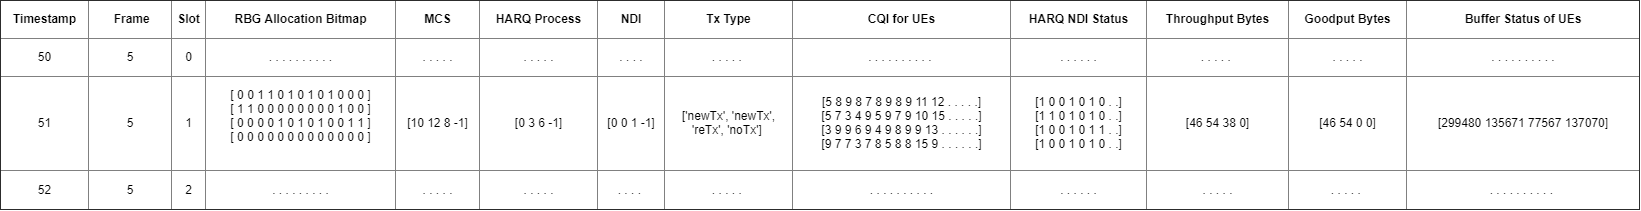

表格的每一行代表一个插槽，并包含以下信息：

- *Timestamp*：自模拟开始以来的时间（以毫秒为单位）。

- *帧*：帧号。

- *Slot*：帧中的插槽号。

- *RBG分配位图*： *N×P*位图矩阵，其中*N*是UE的数量， *P*是RBG的数量。如果一个 RBG 被分配给一个特定的 UE，则相应的比特被设置为 1。例如，[ 0 0 1 1 0 1 0 1 0 1 0 0 0; 1 1 0 0 0 0 0 0 0 0 1 0 0; 0 0 0 0 1 0 1 0 1 0 0 1 1；0 0 0 0 0 0 0 0 0 0 0 0 0]表示UL带宽有13个RBG，UE-1分配了RBG索引：2、3、5、7和9；UE-2 被分配了 RBG 索引 0、1 和 10；UE-3 被分配了 RBG 索引 4、6、8、11 和 12，并且 UE-4 没有被分配任何 RBG。

- *MCS*：长度为*N 的行向量，*其中*N*是 UE 的数量。每个值对应于 PUSCH 传输的调制和编码方案 (MCS) 索引。例如，[10 12 8 -1] 表示只有 UE-1、UE-2 和 UE-3 被分配用于该时隙的 UL 资源，并分别使用 MCS 值 10、12 和 8。

- *HARQ 过程*：长度为*N 的行向量，*其中*N*是 UE 的数量。该值是 UE 用于 PUSCH 传输的 HARQ 进程 ID。例如，[0 3 6 -1] 表示只有 UE-1、UE-2 和 UE-3 被分配用于该时隙的 UL 资源，并分别使用 HARQ 进程 ID 0、3 和 6。

- *NDI*：长度为*N 的行向量，*其中*N*是 UE 的数量。该值是 PUSCH 传输的 UL 分配中的 NDI 标志值。例如，[0 0 1 -1] 表示只有 UE-1、UE-2 和 UE-3 被分配了用于该时隙的 UL 资源并使用 NDI 标志值（确定是使用新传输还是重传) 分别为 0、0 和 1。

- *Tx Type*：Tx Type 指定传输类型（新传输或重传）。长度为*N 的行向量，*其中*N*是 UE 的数量。可能的值是“`newTx`”、“`reTx`”或“`noTx`”。'`noTx`' 表示没有为 UE 分配 PUSCH 资源。例如，['`newTx`' '`newTx`' '`reTx`' '`noTx`'] 表示只有 UE-1、UE-2 和 UE-3 被分配了用于该时隙的 UL 资源。UE-1 和 UE-2 从指定的 HARQ 进程发送一个新的数据包，而 UE-3 在指定的 HARQ 进程的缓冲区中重新发送数据包。

- *UE 的 CQI*： *N×P*矩阵，其中*N*是 UE 的数量， *P*是带宽中的 RB 数量。位置*(i, j)*处的矩阵元素对应于在 RB *j处具有 RNTI* *i*的 UE 的 UL CQI 值。

- *HARQ NDI 状态*： *N×P*矩阵，其中*N*是 UE 的数量， *P*是 UE 上的 HARQ 进程的数量。位置*(i, j)处的矩阵元素是在 UE* *i*处针对 HARQ 进程 ID *j*最后接收到的 NDI 标志。对于新传输，该值和 PUSCH 分配中的 NDI 标志必须切换。例如，在调度日志中描述的帧 5 的时隙 1 中，UE-1 使用 HARQ ID 0，并且 UE-1 处 HARQ ID 0 的最后 NDI 标志值为 1。为了指示新传输，NDI 标志值在 PUSCH 分配中变为 0。

- *吞吐量字节*：长度为*N 的行向量，*其中*N*是 UE 的数量。这些值表示 UE 在此时隙中传输的 MAC 字节。

- *Goodput Bytes*：长度为*N 的行向量，*其中*N*是 UE 的数量。这些值表示 UE 在该时隙中发送的新传输 MAC 字节。

- *UE 的缓冲区状态*：长度为*N 的行向量，*其中*N*是 UE 的数量。这些值表示 UE 处未决缓冲区的数量。

**Scheduling assignment logs:** Information of all the scheduling assignments and related information is logged in this file. For details of log format, see the 'Simulation Logs' section of [NR FDD Scheduling Performance Evaluation](docid:5g_ug#mw_12d91b71-808a-45f1-bd06-5776780aafff) example.

**调度分配日志：**所有调度分配的信息和相关信息都记录在这个文件中。该表显示示例日志条目。

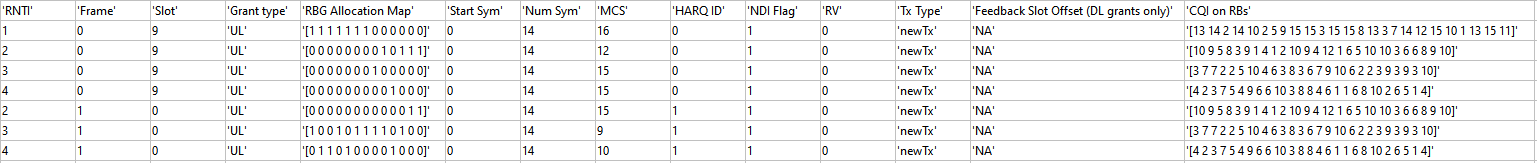

**RLC 日志：RLC 日志**中的每一行代表一个插槽并包含以下信息：

- *时间戳*：时间戳（以毫秒为单位）

- *帧*：帧号。

- *Slot*：帧中的插槽号。

- *UE RLC 统计信息*： *N* × P 小区，其中*N*是 UE 数量和逻辑信道数量的乘积， *P*是收集的统计信息数量。每行代表UE中逻辑信道的统计数据。最后一行包含整个模拟的累积 RLC 统计数据。

- *gNB RLC 统计*： *N* × P 小区，其中*N*是 UE 数量和逻辑信道数量的乘积， *P*是收集的统计信息数量。每一行代表UE在gNB的逻辑信道的统计。最后一行包含整个模拟的累积 RLC 统计数据。

UE和gNB RLC统计表的每一行代表一个UE的逻辑信道，包含：

- *RNTI* : UE 的无线网络临时标识符。

- *LCID*：逻辑通道标识符。

- *TxDataPDU* : RLC 发送到 MAC 层的数据 PDU 的数量。

- *TxDataBytes*：RLC 发送到 MAC 层的数据字节数。

- *ReTxDataPDU*：由 RLC 重传到 MAC 层的数据 PDU 的数量。

- *ReTxDataBytes* : RLC 向 MAC 层重传的数据字节数。

- *TxControlPDU* : RLC 发送到 MAC 层的控制 PDU 的数量。

- *TxControlBytes*：RLC 发送到 MAC 层的控制字节数。

- TxPacketsDropped：由于 Tx 缓冲区溢出而被 RLC 丢弃的 RLC SDU 的数量。

- *TxBytesDropped*：由于 Tx 缓冲区溢出，RLC 丢弃的字节数。

- *TimerPollRetransmitTimedOut*：轮询重传计时器过期的次数。

- *RxDataPDU* : RLC 从 MAC 层接收到的数据 PDU 的数量。

- *RxDataBytes*：RLC 从 MAC 层接收的数据字节数。

- *RxDataPDUDropped*：从 MAC 接收到的数据 PDU 被 RLC 层丢弃的数量。

- *RxDataBytesDropped*：从 MAC 接收到的数据字节数被 RLC 层丢弃。

- *RxDataPDUDuplicate*：RLC 从 MAC 层接收到的重复 PDU 的数量。

- *RxDataBytesDuplicate*：RLC 从 MAC 层接收到的重复数据字节数。

- *RxControlPDU* : RLC 从 MAC 层接收到的控制 PDU 的数量。

- *RxControlBytes*：RLC 从 MAC 层接收的控制字节数。

- *TimerReassemblyTimedOut*：重组计时器过期的次数。

- *TimerStatusProhibitTimedOut*：状态禁止计时器过期的次数。

You can run the script [NRPostSimVisualization](matlab:edit('NRPostSimVisualization.m')) to get a post-simulation visualization of logs. In the post-simulation script, you are provided with variable `isLogReplay`, which provides these options to visualize 'Resource Grid Allocation' and 'Channel Quality Visualization' figures.

- Set `isLogReplay` to `true` for a replay of the simulation logs.

- Set `isLogReplay` to `false` to analyze the simulation logs and input the frame number to visualize the scheduling information of the particular frame

在仿真后脚本中，您将获得变量`isLogReplay`，它提供了这些选项来可视化“资源网格分��配”和“通道质量可视化”数字。

- 设置`isLogReplay`为`true`重放模拟日志。

- 设置`isLogReplay`为`false`分析模拟日志并输入帧号以可视化特定帧的调度信息

% if enableTraces
%     % Read the logs and save them in MAT-files
%     simulationLogs = cell(1, 1);
%     simulationLogs{1} = struct('ULTimeStepLogs',[], 'SchedulingAssignmentLogs',[] ,'RLCLogs',[]);
%     [~, simulationLogs{1}.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger); % UL time step scheduling logs
%     simulationLogs{1}.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger); % Scheduling assignments log
%     simulationLogs{1}.RLCLogs = getRLCLogs(simRLCLogger); % RLC statistics logs
%     save(simulationLogFile, 'simulationLogs'); % Save simulation logs in a MAT-file
%     save(parametersLogFile, 'simParameters'); % Save simulation parameters in a MAT-file
% end

**下面那段程序和上面这个功能差不多**

**BLER logs:** Block error information observed in the uplink and downlink directions are logged in this file. This table shows the sample log entries.在此文件中记录在上行和下行方向观察到的块错误信息。此表显示示例日志条目。

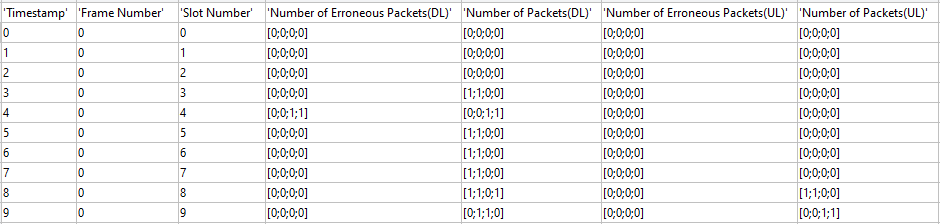

Each row of the log represents one slot. The column contains the information vector of length equal to the number of UEs. Information about a UE is at an index equal to its RNTI.

if enableTraces
    simulationLogs = cell(1,1);
    % Read the logs and save them in MAT-files
    if simParameters.DuplexMode == 0 % FDD
        logInfo = struct('DLTimeStepLogs', [], 'ULTimeStepLogs', [], 'SchedulingAssignmentLogs', [], 'BLERLogs', [], 'AvgBLERLogs', []);
        [logInfo.DLTimeStepLogs, logInfo.ULTimeStepLogs] = getSchedulingLogs(simSchedulingLogger);
    else % TDD
        logInfo = struct('TimeStepLogs', [], 'SchedulingAssignmentLogs', [], 'BLERLogs', [], 'AvgBLERLogs', []);
        logInfo.TimeStepLogs = getSchedulingLogs(simSchedulingLogger);
    end
    [logInfo.BLERLogs, logInfo.AvgBLERLogs] = getBLERLogs(simPhyLogger); % BLER logs
    logInfo.SchedulingAssignmentLogs = getGrantLogs(simSchedulingLogger); % Scheduling assignments log
    simulationLogs{1} = logInfo;
    save(parametersLogFile, 'simParameters'); % Save simulation parameters in a MAT-file
    save(simulationLogFile, 'simulationLogs'); % Save simulation logs in a MAT-file
end

You can run the script [NRPostSimVisualization](matlab:edit('NRPostSimVisualization.m')) to get a post-simulation visualization of logs. For more details about the options to run this script, refer to the [NR FDD Scheduling Performance Evaluation](docid:5g_ug#mw_12d91b71-808a-45f1-bd06-5776780aafff) example 

## Further Exploration

You can use this example to further explore these options.

### Custom scheduling

You can modify the existing scheduling strategy to implement a custom one. [Plug In Custom Scheduler in System-Level Simulation](docid:5g_ug#mw_f50a4203-9daf-4dec-88b0-6d0bc8070d5b) example explains how to create a custom scheduling strategy and plug it into system-level simulation.

您可以修改现有的调度策略来实现自定义的。[Plug In Custom Scheduler in System-Level Simulation](https://ww2.mathworks.cn/help/5g/ug/nr-plug-custom-scheduler-in-system-level-simulation.html)示例说明了如何创建自定义调度策略并将其插入系统级仿真。

### Use passthrough physical layer

For MAC focused simulations, you can use the passthrough PHY layer by installing passthrough PHY layer object on nodes. For gNB create an object of type [hNRGNBPassthroughPhy](matlab:edit('hNRGNBPassthroughPhy.m')), and for UE create an object of type [hNRUEPassthroughPhy](matlab:edit('hNRUEPassthroughPhy.m')). For details, see 'gNB and UEs setup' section of [NR FDD Scheduling Performance Evaluation](docid:5g_ug#mw_12d91b71-808a-45f1-bd06-5776780aafff) example.对于以 MAC 为重点的模拟，您可以通过在节点上配置直连 PHY 层对象来使用直连 PHY 层。

Based on described simulation parameters, the example evaluates the performance of the system measured in terms of various metrics. Different visualizations show the run time performance of the system. A more thorough post-simulation analysis by using the saved logs gives a detailed picture of the operations on a per slot basis.

### Use RLC AM

You can also switch the operating mode of an RLC entity from UM to acknowledged mode (AM) by modifying the input structure fields `EntityType` and `SeqNumFieldLength` in the `configureLogicalChannel` function of [hNRNode.m](matlab:edit('hNRNode.m')). For more details, see the 'Further Exploration' section of [NR FDD Scheduling Performance Evaluation](docid:5g_ug#mw_12d91b71-808a-45f1-bd06-5776780aafff).也可以将 RLC 实体的操作模式从 UM 切换到确认模式 (AM) 

*Copyright 2020-2021 The MathWorks, Inc.*